# Using DALL·E

This script demonstrates an interaction with the OpenAI Images API that generates or modify images using DALL·E models..

% use the valid API key from the paid OpenAI API account
loadenv("../openai.env")
addpath('..') 

## Image Generation with DALL·E 3

Create a DALLE object.

dalle = openAIText2Images("dall-e-3");

Ask DALLE to generate an image of a sea otter. 

[images,resp] = generateImages(dalle,"A cute baby bear climbing a tree with a lake in the back");

Loop through the returned images. 

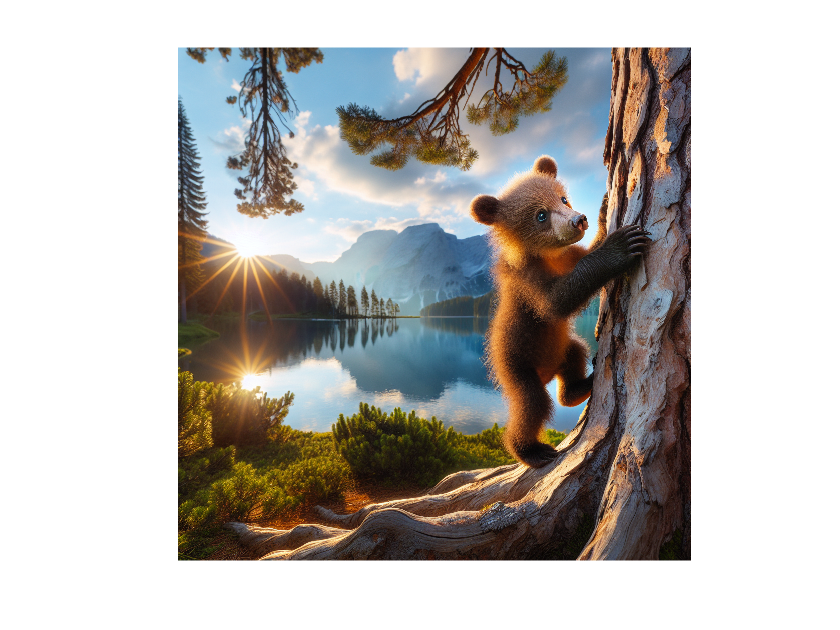

if ~isempty(images)
    tiledlayout('flow')
    for ii = 1:numel(images)
        nexttile
        imshow(images{ii})
    end
else
    disp(resp.Body.Data.error)
end

## Get image variations with DALL·E 2

You can also use image variation feature in DALL·E 2. This feature is not supported in DALL·E 3.

Show the image we want to get variations for. 

im = imread('images\bear.png');
imshow(im)

Get variations. The DALLE object automatically switches to DALL·E 2 to generate variations. 

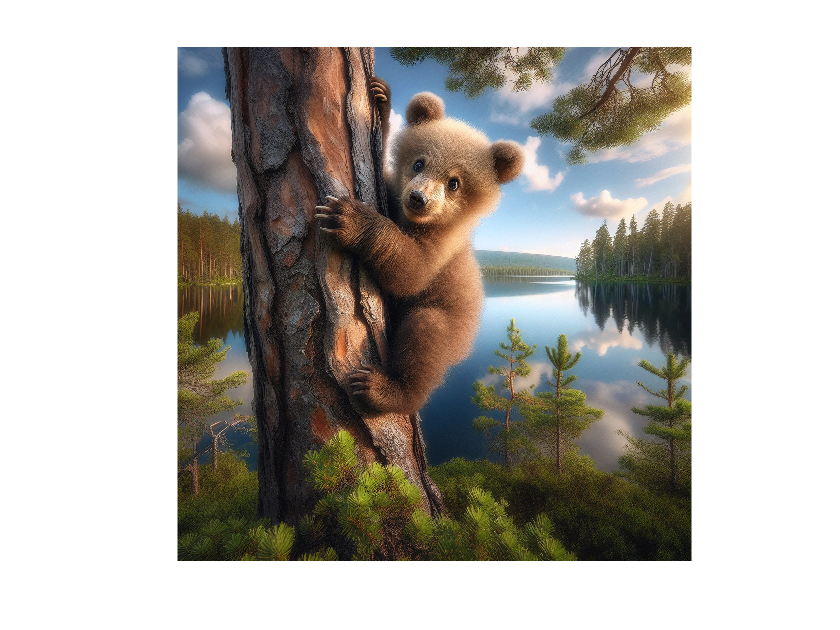

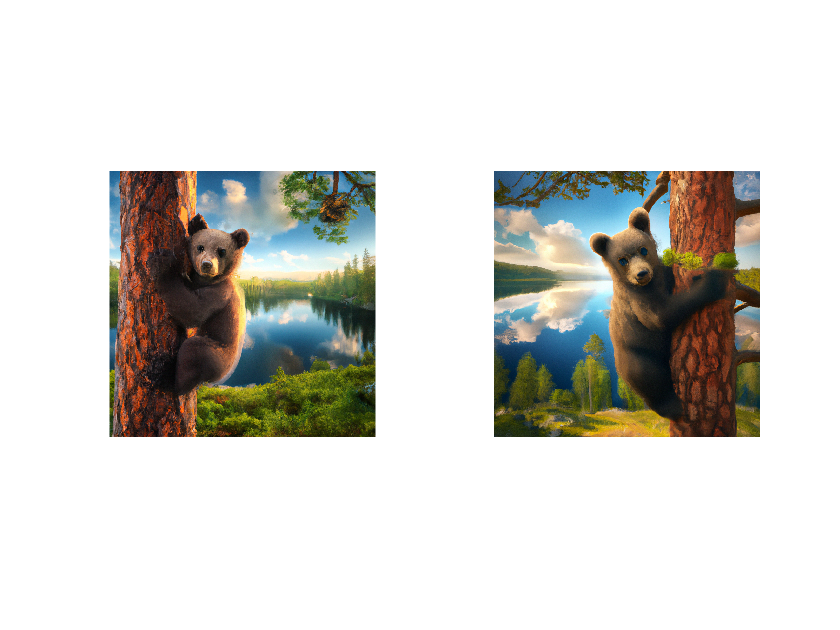

[images,resp] = varyImage(dalle,"images/bear.png",NumImages=2);
if ~isempty(images)
    tiledlayout('flow')
    for ii = 1:numel(images)
        nexttile
        imshow(images{ii})
    end
else
    disp(resp.Body.Data.error)
end

## Edit an Image with DALL·E 2

You can also use image editing feature in DALL·E 2. This feature is not supported in DALLE·E 3.

In this example, we use a mask image to add a swan to the exisitng image. 

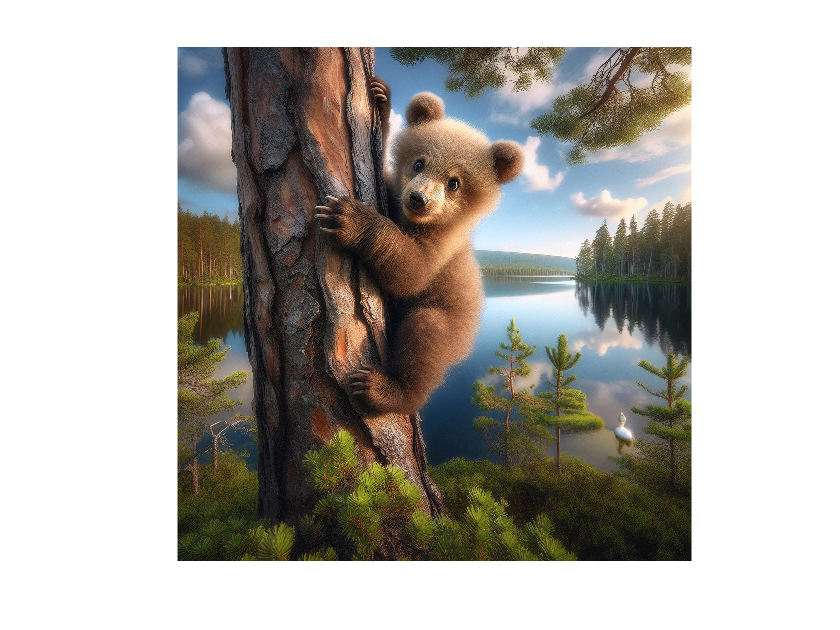

[images,resp] = editImage(dalle,"images/bear.png","Add a white swan",MaskImagePath="images/bear_mask.png");
if isfield(resp.Body.Data,'data')
    figure
    imshow(images{1});
else
    disp(resp.Body.Data.error)
end

*Copyright 2024 The MathWorks, Inc.*